# Lab 3: Hough Transform

## Provided Code

### Setup

close all;
clear all;

### Edge Detection

First the image is read and the edges are identified.

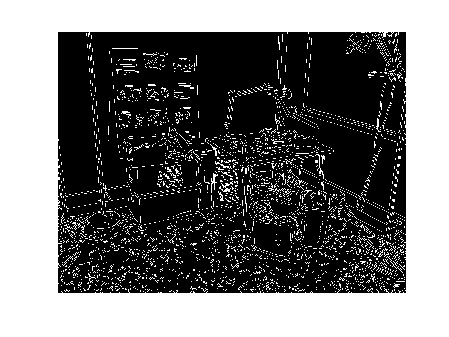

% Read image
I = imread('cluttera2.jpg');

% The image is RGB and we need to convert to grayscale
I = rgb2gray(I);

% Apply your favourite edge detector: Here I am using Built-in Canny
BW = edge(I, 'Canny');

% Show original image
figure;
subplot(1,2,1)
imshow(I);
title('Original');

% Show the calculated image (edge map)
subplot(1,2,2)
imshow(BW)
title('Edge Map');

% Check how edge method performs
help edge

 edge Find edges in intensity image.
    edge takes an intensity or a binary image I as its input, and returns a
    binary image BW of the same size as I, with 1's where the function
    finds edges in I and 0's elsewhere.
 
    edge supports six different edge-finding methods:
 
       The Sobel method finds edges using the Sobel approximation to the
       derivative. It returns edges at those points where the gradient of
       I is maximum.
 
       The Prewitt method finds edges using the Prewitt approximation to
       the derivative. It returns edges at those points where the gradient
       of I is maximum.
 
       The Roberts method finds edges using the Roberts approximation to
       the derivative. It returns edges at those points where the gradient
       of I is maximum.
 
       The Laplacian of Gaussian method finds edges by looking for zero
       crossings after filtering I with a Laplacian of Gaussian filter.
 
   

### Hough Transform

Secondly, **Hough Transform** is performed via in-built function.

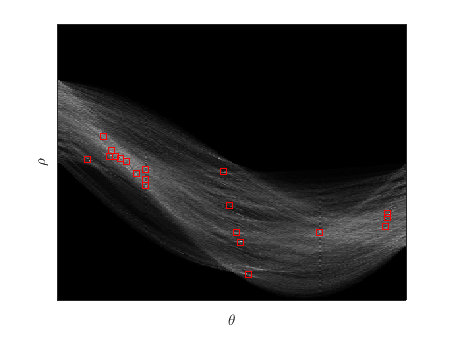

% Calculate the Hough Transform
[H,T,R] = hough(BW);

% Calculate Hough Peaks (number of votes per line as in Lecture)
P = houghpeaks(H, 10, 'threshold', ceil(0.3*max(H(:))));
x = T(P(:,2));
y = R(P(:,1));

% Show the Hough Map and the identified peaks (features)
figure;
imshow(H,[],'XData',T,'YData',R,'InitialMagnification','fit');
xlabel('\theta'), ylabel('\rho');
axis on, axis normal, hold on;
title('Hough Transform');
plot(x, y,'s','color','red');

% Check hough and houghpeaks method
help hough

 hough Hough transform.
    hough implements the Standard Hough Transform. hough is designed
    to detect lines. It uses the parametric representation of a line:
 
                        rho = x*cos(theta) + y*sin(theta).
 
    The variable rho is the distance from the origin to the line along a
    vector perpendicular to the line.  Theta is the angle between
    the x-axis and this vector.
 
    The Standard Hough Transform (SHT) is a parameter space matrix whose
    rows and columns correspond to rho and theta values respectively. The
    elements in the SHT represent accumulator cells. Initially, each cell
    is set to zero. Then, for every nonbackground point in the image, rho
    is calculated for every theta. Rho is rounded off to the nearest
    allowed row in SHT. That accumulator cell is incremented. At the end of
    this procedure, a value of Q in SHT(r,c) means that Q points in the XY
    plane lie on the line specified

help houghpeaks

 houghpeaks Identify peaks in Hough transform.
    PEAKS = houghpeaks(H,NUMPEAKS) locates peaks in the Hough
    transform matrix, H, generated by the HOUGH function. NUMPEAKS
    specifies the maximum number of peaks to identify. PEAKS is
    a Q-by-2 matrix, where Q can range from 0 to NUMPEAKS. Q holds
    the row and column coordinates of the peaks. If NUMPEAKS is
    omitted, it defaults to 1.
 
    PEAKS = houghpeaks(...,PARAM1,VAL1,PARAM2,VAL2) sets various
    parameters. Parameter names can be abbreviated, and case
    does not matter. Each string parameter is followed by a value
    as indicated below:
 
    'Threshold' Nonnegative scalar.
                Values of H below 'Threshold' will not be considered
                to be peaks. Threshold can vary from 0 to Inf.
 
                Default: 0.5*max(H(:))
 
    'NHoodSize' Two-element vector of positive odd integers: [M N].
                'NHoodSize' specifies the size o

### Line Detection

Finally, the lines are found.

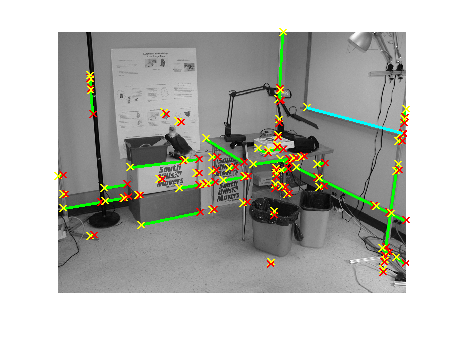

% Find lines and plot them
lines = houghlines(BW, T, R, P,'FillGap', 5, 'MinLength', 7);

% Prepare plot
figure;
imshow(I,[]);
hold on
max_len = 0;

for k = 1:length(lines)
    xy = [lines(k).point1; lines(k).point2];
    plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');
    
    % Plot beginnings and ends of lines
    plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');
    plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');
    
    % Determine the endpoints of the longest line segment
    len = norm(lines(k).point1 - lines(k).point2);
    if ( len > max_len)
        max_len = len;
        xy_long = xy;
    end
end

% Highlight the longest line segment
plot(xy_long(:,1),xy_long(:,2),'LineWidth',2,'Color','cyan');

% Check line detection method
help houghlines

 houghlines Extract line segments based on Hough transform.
    LINES = houghlines(BW, THETA, RHO, PEAKS) extracts line segments
    in the image BW associated with particular bins in a Hough 
    transform.  THETA and RHO are vectors returned by function HOUGH.
    Matrix PEAKS, which is returned by function HOUGHPEAKS,
    contains the row and column coordinates of the Hough transform 
    bins to use in searching for line segments. houghlines returns
    LINES structure array whose length equals the number of merged
    line segments found. Each element of the structure array has
    these fields: 
 
       point1  End-point of the line segment; two-element vector
       point2  End-point of the line segment; two-element vector
       theta   Angle (in degrees) of the Hough transform bin
       rho     Rho-axis position of the Hough transform bin
 
    The end-point vectors contain [X, Y] coordinates.
 
    LINES = houghline

## Tasks

### Task 1

#### Edge Detection

Firstly, the algorithm takes an image, converts it to greyscale and applies **Canny Edge Detection** technique to identify borders. It applies Gaussian filter derivative to compute image gradients, computes their magnitude, applies **Non-maxima Suppression** and **Hysteresis Thresholding**. The output is a binary image matrix with pixels with values of 1 indicating edges.

This corresponds to the MATLAB documentation:

"*The Canny method finds edges by looking for local maxima of the gradient of I. The gradient is calculated using the derivative of a Gaussian filter. The method uses two thresholds, to detect strong and weak edges, and includes the weak edges in the output only if they are connected to strong edges. This method is therefore less likely than the others to be "fooled" by noise, and more likely to detect true weak edges.*"

Note that the threshold values are determined automatically and the default sigma value is sqrt(2)

Ref: Canny, John, "A Computational Approach to Edge Detection," *IEEE Transactions on Pattern Analysis and Machine Intelligence,* Vol. PAMI-8, No. 6, 1986, pp. 679-698.

#### Hough Transform

Secondly, the algorithm applies standard **Hough Transform,** where it takes a binary image matrix and transforms image space to **Hough** space (maps points to sinusoids). It digitalizes each line to a parameter matrix where each entry is incremented if a discrete line passes through that matrix cell. The output is the matrix itself with rows representing possible magnitudes and columns representing all possible angles. It also returns an array of considered angles and an array of considered magnitudes.

This corresponds to the MATLAB documentation:

"*h*`ough c`*omputes the Standard Hough Transform (SHT) of the binary image *`BW`*. The *`hough`*                                function is designed to detect lines. The function uses the parametric representation of a line: *`rho = x*cos(theta) + y*sin(theta)`*. The function returns *`rho`*, the distance from the origin to the line along a vector perpendicular to the line, and *`theta`*, the angle in degrees between the x-axis and this vector.*"

Ref: Rafael C. Gonzalez, Richard E. Woods, Steven L. Eddins, "Digital Image Processing Using MATLAB", 2nd ed., Gatesmark Publishing, 2009

Thirdly, the algorithm finds **Hough Peaks** - it takes in the **Hough Transform** matrix and finds up to specified number of peaks (in the provided case, up to 10), whith a specific minimum threshold (in the provided case, 0.3 times the maximum value of the **Hough** matrix). The output is a coordinate matrix with rows representing coordinates of the peaks in the parameter matrix.

This corresponds to the MATLAB documentation:

"*houghpeaks locates peaks in the Hough transform matrix, *`H`*, generated by the *[`hough`](https://uk.mathworks.com/help/images/ref/hough.html)* function. *`numpeaks`* specifies the maximum number of peaks to identify.*"

Ref: Rafael C. Gonzalez, Richard E. Woods, Steven L. Eddins, "Digital Image Processing Using MATLAB", Prentice Hall, 2004

#### Line Detection

Finally, the line segments are extracted via `houghlines` method. It takes in the **Hough** matrix, *theta* and *rho* values as well as calculated peaks and computes the line segments in the image. A threshold to merge multiple lines to one (in the provided case, 5) amd a minimum line length (in the provided case, 7) can also be specified. The start and the finish of the line is determined by checking the original edge values to check whether there actually should be a line. Idea of edge connectivity is used through named parameter 'FillGap' which is a distance between 2 line segments of the same biin. "*When the distance between the line segments is less than the value specified, the *`houghlines`* function merges the line segments into a single line segment*".

This corresponds to the MATLAB documentation:

"`houghlines(`[`BW`](https://uk.mathworks.com/help/images/ref/houghlines.html?docviewer=ml_online#mw_a6dd2036-53c1-4fc4-a63a-ac870658ff37)`,`[`theta`](https://uk.mathworks.com/help/images/ref/houghlines.html?docviewer=ml_online#buwgo_f-1-theta)`,`[`rho`](https://uk.mathworks.com/help/images/ref/houghlines.html?docviewer=ml_online#buwgo_f-1-rho)`,`[`peaks`](https://uk.mathworks.com/help/images/ref/houghlines.html?docviewer=ml_online#buwgo_f-1-peaks)`) `*extracts line segments in the image *`BW`*                                associated with particular bins in a Hough transform. *`theta`* and *`rho`* are vectors returned by function *`hough`*. *`peaks`* is a matrix returned by the *`houghpeaks`* function that contains the row and column coordinates of the Hough transform bins to use in searching for line segments*"

Ref: Rafael C. Gonzalez, Richard E. Woods, Steven L. Eddins, "Digital Image Processing Using MATLAB", Prentice Hall, 2003

### Task 2

By decresing the maximum number of peaks, only the brightest ones are marked in the **Hough Map**. After extracting lines, few clear long lines can be seen (in the chosen case, 5) with few to no very short line segments. This is because at very bright peaks many sinusoids overlap, meaning many points on the same line, thus longer edge regions.

By increasing the maximum number of peaks, the opposite can be observed - less bright peaks are marked in the **Hough Map**, meaning there are lines made up of not as many edge points and also such lines consist of short line segments rather than being solid long lines.

### Task 3

Assuming the thresholds for each edge detection method are chosen such that they produce similar edge maps and assuming all parameters for **Hough Transform** are kept the same, it seems that *Canny* technique provides the best results due to its edge smoothness in the edge map, even though other filters seem to identify the specified number of lines (10 in the given case) at the same or very similar positions (note: not line segments but the general lines themselves). 

**Roberts** - due to a slightly higher threshold than for *Prewitt* and *Sobel* filters it shows less noise in the line map, i.e., it has less short line segments. Overall it captures the lines quite well, likely because it captures diagonal edges which the image posesses (boundaries are slightly tilted). It still lacks completeness for some lines, such as for the black vertical "pipe" on the left, showing that edges should be smoother for them to correspond with the line endpoints.

**Prewitt** - because this filter is larger, a slightly lower threshold compared to *Roberts* filter is enough because this filter is smoother. It still, however induces a bit more noise (due to lower threshold) meaning there are more short line segments in the line map. It is better at recognizing vertical lines than *Roberts* map and generally the longest lines are longer than the longest lines when using the *Roberts* filter because of more certainty in the edges.

**Sobel** - produces very similar results to *Prewitt*, however it is better because there is less noise due to larger weights in the filter on the center pixels meaning the edge map is more accurate. It has also less false line segments (segments which do not correspond to the actual edges) again because of less noise - the line detection method does not connect false positive lines simply because noise does not introduce them.

**Laplassian of Gaussian** - this method produces great results with minimal noise. This is because the Gaussian part of the method averages the noise out and the Laplassian part detects the edges more precisely due to the use of the 2nd order derivative. The breaking points of line segments are even more precise than when using *Canny* filter. Likely, zero-crossing points align better than thresholded points, thus giving more precide line segments. It still lacks some major lines, such as the side of the whiteboard, compared to when using *Canny* - it does not have such great connectivity for weak edges (*Canny* tackles that with *Hysteresis thresholding*). It could potentially be a better method than *Canny* if played wel with *Hough* line detection parameters.